syms g L_1 L_2

syms L__d_g1 L__d_g2 m__d_1 m__d_2 I__d_1 I__d_2 I__d_m1 n_1 I__d_m2 n_2
syms psi_1 psi_dot_1 psi_ddot_1 psi_2 psi_dot_2 psi_ddot_2
syms tau__d_1 tau__d_2

syms L__i_g1 L__i_g2 m__i_1 m__i_2 I__i_1 I__i_2
syms theta_1 theta_dot_1 theta_ddot_1 theta_2 theta_dot_2 theta_ddot_2
syms tau__i_1 tau__i_2

**Paste EOM here:**

device_eqn = [(m__d_2*L_1^2 + m__d_1*L__d_g1^2 + I__d_m1*n_1^2 + I__d_1)*psi_ddot_1 + L_1*L__d_g2*m__d_2*sin(psi_1 - psi_2)*psi_dot_2^2 + L_1*g*m__d_2*cos(psi_1) + L__d_g1*g*m__d_1*cos(psi_1) + L_1*L__d_g2*m__d_2*psi_ddot_2*cos(psi_1 - psi_2) == tau__d_1; (m__d_2*L__d_g2^2 + I__d_m2*n_2^2 + I__d_2)*psi_ddot_2 - L_1*L__d_g2*m__d_2*sin(psi_1 - psi_2)*psi_dot_1^2 + L__d_g2*g*m__d_2*cos(psi_2) + L_1*L__d_g2*m__d_2*psi_ddot_1*cos(psi_1 - psi_2) == tau__d_2];
infant_eqn_theta = [(m__i_2*L_1^2 + 2*m__i_2*cos(theta_2)*L_1*L__i_g2 + m__i_1*L__i_g1^2 + m__i_2*L__i_g2^2 + I__i_1 + I__i_2)*theta_ddot_1 + (-2*L_1*L__i_g2*m__i_2*theta_dot_2*sin(theta_2))*theta_dot_1 + I__i_2*theta_ddot_2 + L__i_g2^2*m__i_2*theta_ddot_2 + L__i_g2*g*m__i_2*cos(theta_1 + theta_2) + L_1*g*m__i_2*cos(theta_1) + L__i_g1*g*m__i_1*cos(theta_1) - L_1*L__i_g2*m__i_2*theta_dot_2^2*sin(theta_2) + L_1*L__i_g2*m__i_2*theta_ddot_2*cos(theta_2) == tau__i_1; (m__i_2*L__i_g2^2 + I__i_2)*theta_ddot_2 + I__i_2*theta_ddot_1 + L__i_g2^2*m__i_2*theta_ddot_1 + L__i_g2*g*m__i_2*cos(theta_1 + theta_2) + L_1*L__i_g2*m__i_2*theta_dot_1^2*sin(theta_2) + L_1*L__i_g2*m__i_2*theta_ddot_1*cos(theta_2) == tau__i_2];
infant_eqn_psi = [psi_ddot_1*(m__i_2*L_1^2 + 2*m__i_2*cos(psi_1 - psi_2)*L_1*L__i_g2 + m__i_1*L__i_g1^2 + m__i_2*L__i_g2^2 + I__i_1 + I__i_2) - I__i_2*(psi_ddot_1 - psi_ddot_2) - L__i_g2^2*m__i_2*(psi_ddot_1 - psi_ddot_2) + L_1*g*m__i_2*cos(psi_1) + L__i_g1*g*m__i_1*cos(psi_1) + L__i_g2*g*m__i_2*cos(psi_2) - L_1*L__i_g2*m__i_2*cos(psi_1 - psi_2)*(psi_ddot_1 - psi_ddot_2) + L_1*L__i_g2*m__i_2*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2)^2 - 2*L_1*L__i_g2*m__i_2*psi_dot_1*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2) == tau__i_1; I__i_2*psi_ddot_1 - (m__i_2*L__i_g2^2 + I__i_2)*(psi_ddot_1 - psi_ddot_2) + L__i_g2^2*m__i_2*psi_ddot_1 + L__i_g2*g*m__i_2*cos(psi_2) - L_1*L__i_g2*m__i_2*psi_dot_1^2*sin(psi_1 - psi_2) + L_1*L__i_g2*m__i_2*psi_ddot_1*cos(psi_1 - psi_2) == tau__i_2];

full_eqn = [- I__i_2*(psi_ddot_1 - psi_ddot_2) + psi_ddot_1*(m__i_2*L_1^2 + 2*m__i_2*cos(psi_1 - psi_2)*L_1*L__i_g2 + m__i_1*L__i_g1^2 + m__i_2*L__i_g2^2 + I__i_1 + I__i_2) + (m__d_2*L_1^2 + m__d_1*L__d_g1^2 + I__d_m1*n_1^2 + I__d_1)*psi_ddot_1 - L__i_g2^2*m__i_2*(psi_ddot_1 - psi_ddot_2) + L_1*L__d_g2*m__d_2*sin(psi_1 - psi_2)*psi_dot_2^2 + L_1*g*m__d_2*cos(psi_1) + L__d_g1*g*m__d_1*cos(psi_1) + L_1*L__d_g2*m__d_2*psi_ddot_2*cos(psi_1 - psi_2) + L_1*g*m__i_2*cos(psi_1) + L__i_g1*g*m__i_1*cos(psi_1) + L__i_g2*g*m__i_2*cos(psi_2) - L_1*L__i_g2*m__i_2*cos(psi_1 - psi_2)*(psi_ddot_1 - psi_ddot_2) + L_1*L__i_g2*m__i_2*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2)^2 - 2*L_1*L__i_g2*m__i_2*psi_dot_1*sin(psi_1 - psi_2)*(psi_dot_1 - psi_dot_2) == tau__d_1 + tau__i_1; I__i_2*psi_ddot_1 - (m__i_2*L__i_g2^2 + I__i_2)*(psi_ddot_1 - psi_ddot_2) + (m__d_2*L__d_g2^2 + I__d_m2*n_2^2 + I__d_2)*psi_ddot_2 - L_1*L__d_g2*m__d_2*sin(psi_1 - psi_2)*psi_dot_1^2 + L__d_g2*g*m__d_2*cos(psi_2) + L_1*L__d_g2*m__d_2*psi_ddot_1*cos(psi_1 - psi_2) + L__i_g2^2*m__i_2*psi_ddot_1 + L__i_g2*g*m__i_2*cos(psi_2) - L_1*L__i_g2*m__i_2*psi_dot_1^2*sin(psi_1 - psi_2) + L_1*L__i_g2*m__i_2*psi_ddot_1*cos(psi_1 - psi_2) == tau__d_2 + tau__i_2];

s = solve(device_eqn,[psi_ddot_1 psi_ddot_2]);
device_psi_ddot_1 = s.psi_ddot_1;
device_psi_ddot_2 = s.psi_ddot_2;

s = solve(infant_eqn_theta,[theta_ddot_1 theta_ddot_2]);
infant_theta_ddot_1 = s.theta_ddot_1;
infant_theta_ddot_2 = s.theta_ddot_2;

s = solve(infant_eqn_psi,[psi_ddot_1 psi_ddot_2]);
infant_psi_ddot_1 = s.psi_ddot_1;
infant_psi_ddot_2 = s.psi_ddot_2;

s = solve(full_eqn,[psi_ddot_1 psi_ddot_2]);
full_psi_ddot_1 = s.psi_ddot_1;
full_psi_ddot_2 = s.psi_ddot_2;

**Copy function strings for new ODEs here:**

psi_vars = [psi_1; psi_dot_1; psi_2; psi_dot_2;];
theta_vars = [theta_1; theta_dot_1; theta_2; theta_dot_2;];
device_tau_vars = [tau__d_1; tau__d_2];
infant_tau_vars = [tau__i_1; tau__i_2];
full_tau_vars = [device_tau_vars; infant_tau_vars];

device_ode_string = create_ode_string("device_ode",psi_vars,device_tau_vars,device_psi_ddot_1,device_psi_ddot_2);

device_ode_string =     "function dy = device_ode(t,y,tau,prop)
     I__d_1 = prop.I__d_1;
     I__d_2 = prop.I__d_2;
     I__d_m1 = prop.I__d_m1;
     I__d_m2 = prop.I__d_m2;
     L_1 = prop.L_1;
     L__d_g1 = prop.L__d_g1;
     L__d_g2 = prop.L__d_g2;
     g = prop.g;
     m__d_1 = prop.m__d_1;
     m__d_2 = prop.m__d_2;
     n_1 = prop.n_1;
     n_2 = prop.n_2;
     dy = ...
     [y(2);
     -(L_1*L__d_g2^3*m__d_2^2*y(4)^2*sin(y(1) - y(3)) - I__d_m2*n_2^2*tau(1) - L__d_g2^2*m__d_2*tau(1) - I__d_2*tau(1) + L_1*L__d_g2^2*g*m__d_2^2*cos(y(1)) + I__d_2*L_1*g*m__d_2*cos(y(1)) + I__d_2*L__d_g1*g*m__d_1*cos(y(1)) + L_1*L__d_g2*m__d_2*tau(2)*cos(y(1) - y(3)) - L_1*L__d_g2^2*g*m__d_2^2*cos(y(1) - y(3))*cos(y(3)) + L_1^2*L__d_g2^2*m__d_2^2*y(2)^2*cos(y(1) - y(3))*sin(y(1) - y(3)) + I__d_m2*L_1*g*m__d_2*n_2^2*cos(y(1)) + I__d_m2*L__d_g1*g*m__d_1*n_2^2*cos(y(1)) + L__d_g1*L__d_g2^2*g*m__d_1*m__d_2*cos(y(1)) + I__d_2*L_1*L__d_g2*m__d_2*y(4)^2*sin(y(1) - y(3)) + I__d_m2*L_1*L__d_g2*m__d_2*n_2^2*

infant_theta_ode_string = create_ode_string("infant_theta_ode",theta_vars,infant_tau_vars,infant_theta_ddot_1,infant_theta_ddot_2);

infant_theta_ode_string =     "function dy = infant_theta_ode(t,y,tau,prop)
     I__i_1 = prop.I__i_1;
     I__i_2 = prop.I__i_2;
     L_1 = prop.L_1;
     L__i_g1 = prop.L__i_g1;
     L__i_g2 = prop.L__i_g2;
     g = prop.g;
     m__i_1 = prop.m__i_1;
     m__i_2 = prop.m__i_2;
     dy = ...
     [y(2);
     (I__i_2*tau(1) - I__i_2*tau(2) + L__i_g2^2*m__i_2*tau(1) - L__i_g2^2*m__i_2*tau(2) - L_1*L__i_g2^2*g*m__i_2^2*cos(y(1)) - I__i_2*L_1*g*m__i_2*cos(y(1)) - I__i_2*L__i_g1*g*m__i_1*cos(y(1)) - L_1*L__i_g2*m__i_2*tau(2)*cos(y(3)) + L_1*L__i_g2^3*m__i_2^2*y(2)^2*sin(y(3)) + L_1*L__i_g2^3*m__i_2^2*y(4)^2*sin(y(3)) + L_1*L__i_g2^2*g*m__i_2^2*cos(y(1) + y(3))*cos(y(3)) + L_1^2*L__i_g2^2*m__i_2^2*y(2)^2*cos(y(3))*sin(y(3)) + I__i_2*L_1*L__i_g2*m__i_2*y(2)^2*sin(y(3)) + I__i_2*L_1*L__i_g2*m__i_2*y(4)^2*sin(y(3)) - L__i_g1*L__i_g2^2*g*m__i_1*m__i_2*cos(y(1)) + 2*L_1*L__i_g2^3*m__i_2^2*y(2)*y(4)*sin(y(3)) + 2*I__i_2*L_1*L__i_g2*m__i_2*y(2)*y(4)*sin(y(3)))/(I__i_1*I__i_2 + L_1^2*L__i_g2^2*m__i

infant_psi_ode_string = create_ode_string("infant_psi_ode",psi_vars,infant_tau_vars,infant_psi_ddot_1,infant_psi_ddot_2);

infant_psi_ode_string =     "function dy = infant_psi_ode(t,y,tau,prop)
     I__i_1 = prop.I__i_1;
     I__i_2 = prop.I__i_2;
     L_1 = prop.L_1;
     L__i_g1 = prop.L__i_g1;
     L__i_g2 = prop.L__i_g2;
     g = prop.g;
     m__i_1 = prop.m__i_1;
     m__i_2 = prop.m__i_2;
     dy = ...
     [y(2);
     -(I__i_2*tau(2) - I__i_2*tau(1) - L__i_g2^2*m__i_2*tau(1) + L__i_g2^2*m__i_2*tau(2) + L_1*L__i_g2^3*m__i_2^2*y(4)^2*sin(y(1) - y(3)) + L_1*L__i_g2^2*g*m__i_2^2*cos(y(1)) + I__i_2*L_1*g*m__i_2*cos(y(1)) + I__i_2*L__i_g1*g*m__i_1*cos(y(1)) + L_1*L__i_g2*m__i_2*tau(2)*cos(y(1) - y(3)) - L_1*L__i_g2^2*g*m__i_2^2*cos(y(1) - y(3))*cos(y(3)) + L_1^2*L__i_g2^2*m__i_2^2*y(2)^2*cos(y(1) - y(3))*sin(y(1) - y(3)) + L__i_g1*L__i_g2^2*g*m__i_1*m__i_2*cos(y(1)) + I__i_2*L_1*L__i_g2*m__i_2*y(4)^2*sin(y(1) - y(3)))/(I__i_1*I__i_2 + L_1^2*L__i_g2^2*m__i_2^2 + I__i_2*L_1^2*m__i_2 + I__i_2*L__i_g1^2*m__i_1 + I__i_1*L__i_g2^2*m__i_2 + L__i_g1^2*L__i_g2^2*m__i_1*m__i_2 - L_1^2*L__i_g2^2*m__i_2^2*cos(y(1) -

full_ode_string = create_ode_string("full_ode",psi_vars,full_tau_vars,full_psi_ddot_1,full_psi_ddot_2);

full_ode_string =     "function dy = full_ode(t,y,tau,prop)
     I__d_1 = prop.I__d_1;
     I__d_2 = prop.I__d_2;
     I__d_m1 = prop.I__d_m1;
     I__d_m2 = prop.I__d_m2;
     I__i_1 = prop.I__i_1;
     I__i_2 = prop.I__i_2;
     L_1 = prop.L_1;
     L__d_g1 = prop.L__d_g1;
     L__d_g2 = prop.L__d_g2;
     L__i_g1 = prop.L__i_g1;
     L__i_g2 = prop.L__i_g2;
     g = prop.g;
     m__d_1 = prop.m__d_1;
     m__d_2 = prop.m__d_2;
     m__i_1 = prop.m__i_1;
     m__i_2 = prop.m__i_2;
     n_1 = prop.n_1;
     n_2 = prop.n_2;
     dy = ...
     [y(2);
     -(I__i_2*tau(2) - I__d_2*tau(3) - I__i_2*tau(1) - I__d_2*tau(1) - I__i_2*tau(3) + I__i_2*tau(4) - I__d_m2*n_2^2*tau(1) - I__d_m2*n_2^2*tau(3) - L__d_g2^2*m__d_2*tau(1) - L__d_g2^2*m__d_2*tau(3) - L__i_g2^2*m__i_2*tau(1) + L__i_g2^2*m__i_2*tau(2) - L__i_g2^2*m__i_2*tau(3) + L__i_g2^2*m__i_2*tau(4) + L_1*L__d_g2^3*m__d_2^2*y(4)^2*sin(y(1) - y(3)) + L_1*L__i_g2^3*m__i_2^2*y(4)^2*sin(y(1) - y(3)) + L_1*L__d_g2^2*g*m__d_2^2*cos(y(1)) + L_1*

prop = [];
prop.g = 9.81;
prop.L_1 = 1;
prop.L_2 = 1;

prop.L__d_g1 = 1;
prop.L__d_g2 = 1;
prop.m__d_1 = 1;
prop.m__d_2 = 1;
prop.I__d_1 = 1;
prop.I__d_2 = 1;
prop.I__d_m1 = 1;
prop.I__d_m2 = 1;
prop.n_1 = 1;
prop.n_2 = 1;

prop.L__i_g1 = 1;
prop.L__i_g2 = 1;
prop.m__i_1 = 1;
prop.m__i_2 = 1;
prop.I__i_1 = 1;
prop.I__i_2 = 1;

Hanging Test: Do all systems remain at rest when hanging vertically?

ang_tol = 1e-4;
tspan = [0 1];

tau = [0 0];
y0 = [-pi/2 0 -pi/2 0];
[t,y] = ode45(@(t,y) device_ode(t,y,tau,prop), tspan, y0);
static_check_d = abs(y0 - y(end,:)) < ang_tol

static_check_d = 1×4 logical array
   1   1   1   1


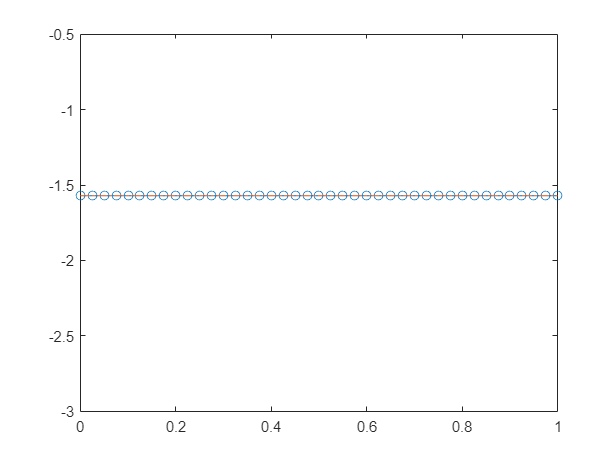

plot(t,y(:,1),'-o',t,y(:,3),'-.')


tau = [0 0];
y0 = [-pi/2 0 0 0];
[t,y] = ode45(@(t,y) infant_theta_ode(t,y,tau,prop), tspan, y0);
static_check_i_theta = abs(y0 - y(end,:)) < ang_tol

static_check_i_theta = 1×4 logical array
   1   1   1   1


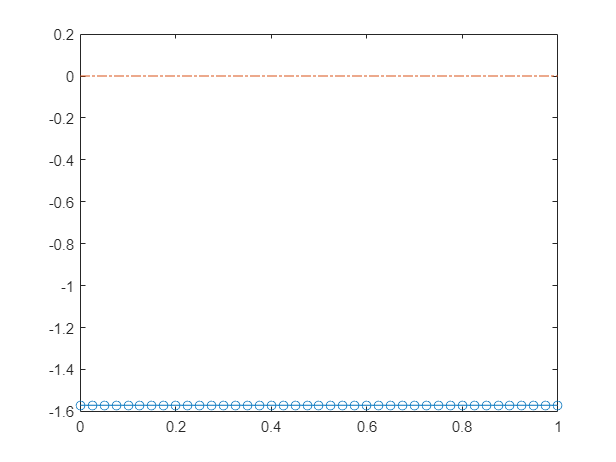

plot(t,y(:,1),'-o',t,y(:,3),'-.')


tau = [0 0];
y0 = [-pi/2 0 -pi/2 0];
[t,y] = ode45(@(t,y) infant_psi_ode(t,y,tau,prop), tspan, y0);
static_check_i_psi = abs(y0 - y(end,:)) < ang_tol

static_check_i_psi = 1×4 logical array
   1   1   1   1


plot(t,y(:,1),'-o',t,y(:,3),'-.')


tau = [0 0 0 0];
y0 = [-pi/2 0 -pi/2 0];
[t,y] = ode45(@(t,y) full_system_ode(t,y,tau,prop), tspan, y0);
static_check_f = abs(y0 - y(end,:)) < ang_tol

static_check_f = 1×4 logical array
   1   1   1   1


plot(t,y(:,1),'-o',t,y(:,3),'-.')


hanging_test_passed = all([static_check_d static_check_i_theta static_check_i_psi static_check_f])

hanging_test_passed = logical
   1


Substitution Test: Was the infant system successfully converted? Do the systems have the same output when dropped from the horizontal position?

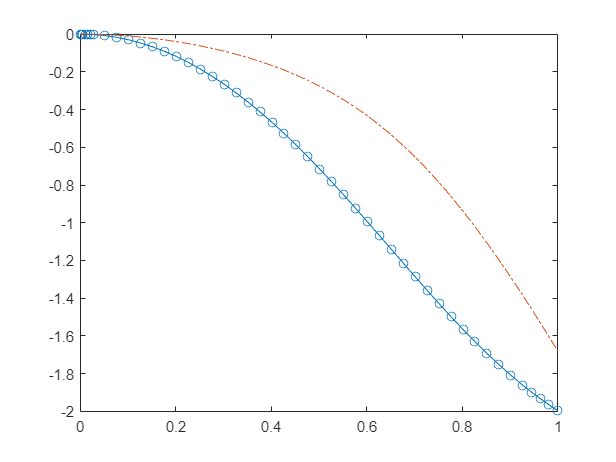

tau = [0 0];
y0 = [0 0 0 0];
[t_theta,theta] = ode45(@(t,theta) infant_theta_ode(t,theta,tau,prop), tspan, y0);
converted_psi = [theta(:,1:2) theta(:,1)+theta(:,3) theta(:,2)+theta(:,4)];
plot(t_theta,converted_psi(:,1),'-o',t_theta,converted_psi(:,3),'-.')


tau = [0 0];
y0 = [0 0 0 0];
[t_psi,psi] = ode45(@(t,psi) infant_psi_ode(t,psi,tau,prop), tspan, y0);
plot(t_psi,psi(:,1),'-o',t_psi,psi(:,3),'-.')


substitution_test_passed = abs(converted_psi(end)-psi(end)) < ang_tol

substitution_test_passed = logical
   1
